% dummy mri data
n = 1000;
x = rand(n,1)*10;
y = rand(n,1)*-10;
s = 0.8 + ...
    sqrt(x.^2 + y.^2)*0.2 + ...
    (rand(n,1)-0.5);

% dummy ephys data
N = 5000;
X = rand(N,1)*10;
Y = rand(N,1)*-10;
S = 3.6 + ...
    sqrt(X.^2 + Y.^2)*0.24 + ...
    1.2*(rand(N,1)-0.5);

%% interpolate x,y,s surfaces
[xq,yq] = meshgrid(0:.1:10,-10:.1:0);
Xq=xq; Yq=yq;

sq = griddata(x,y,s,xq,yq,'cubic');
Sq = griddata(X,Y,S,Xq,Yq,'cubic');

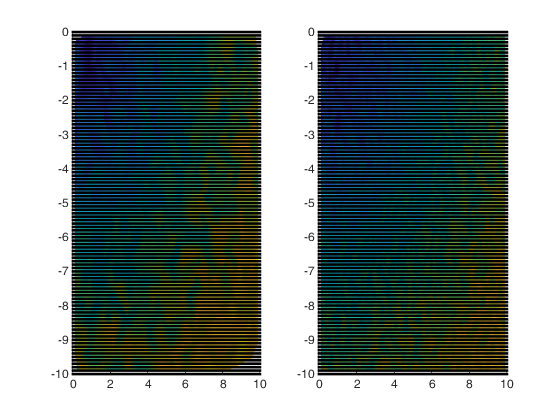

%% plot interpolated surfaces through the data
subplot(1,2,1);hold on;
contourf(xq,yq,sq,'LevelStep',0.1,'LineStyle','none');
plot(xq,yq,'k.')

subplot(1,2,2);hold on;
contourf(Xq,Yq,Sq,'LevelStep',0.1,'LineStyle','none');
plot(Xq,Yq,'k.')

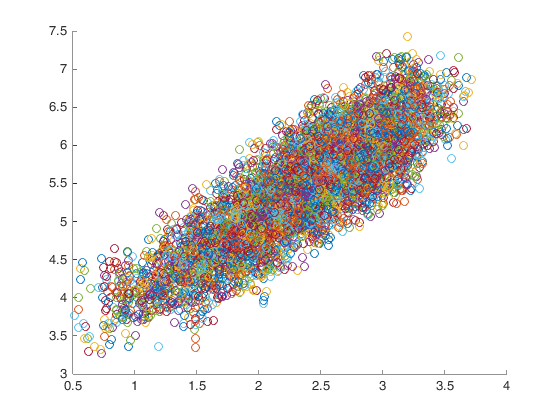

%% bootstrap the correlation analysis
np=100; nb=100;
v = find(~isnan(sq));
cc=[]; 
figure; hold on;
for i=1:nb
    V=v(randperm(length(v)));
    [r,p]=corrcoef(sq(V(1:np)), Sq(V(1:np)));
    scatter(sq(V(1:np)), Sq(V(1:np)),'o');
    cc=[cc; r(2)]; 
end

fprintf(['Mean CC: ' num2str(mean(cc)) '\n']);

Mean CC 0.84658


fprintf(['stdev: ' num2str(std(cc)) '\n']);

stdev: 0.02088
